# Data analysis

First, we plot the box plots

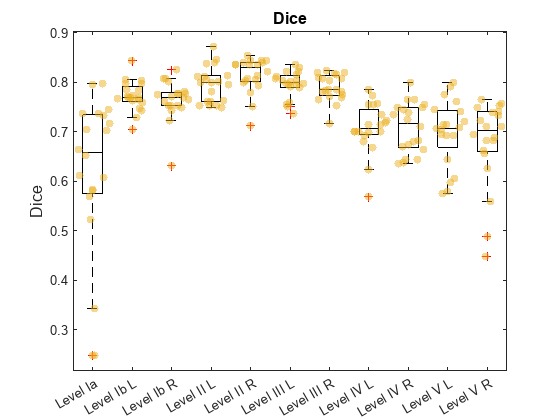

x = repmat(1:11,20,1);

nameToFind = [ {'Level Ia' }, {'Level Ib L' }, {'Level Ib R' }, ...
        {'Level II L' }, {'Level II R' }, {'Level III L'}, ...
        {'Level III R'}, {'Level IV L' }, {'Level IV R' }, ...
        {'Level V L'  }, {'Level V R'  }];

figure(1)
boxplot(similarity.dice, nameToFind, ...
    Colors='k', BoxStyle='outline')
hold on
ylabel('Dice', 'FontSize', 12)
title('Dice', 'FontSize', 12)
swarmchart(x, similarity.dice, [], ...
    [0.9290 0.6940 0.1250],'filled','MarkerFaceAlpha',0.5, ...
    'MarkerEdgeAlpha',0.5)
hold off
saveas(gcf, '\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\dice.png')

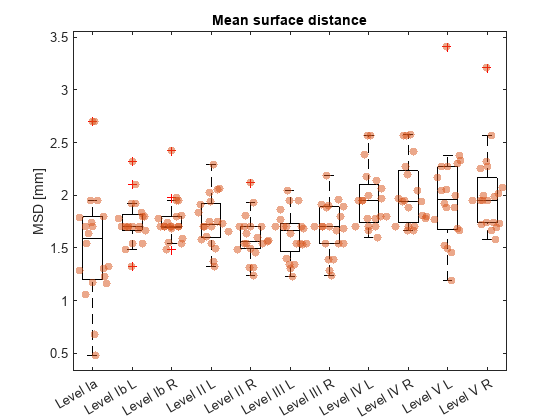



figure(2)
boxplot(similarity.MSD, nameToFind, ...
    Colors='k', BoxStyle='outline')
hold on
title('Mean surface distance')
ylabel('MSD [mm]')
swarmchart(x, similarity.MSD, [], ...
    [0.8500 0.3250 0.0980],'filled','MarkerFaceAlpha',0.5, ...
    'MarkerEdgeAlpha',0.5) 
hold off
saveas(gcf, '\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\msd.png')

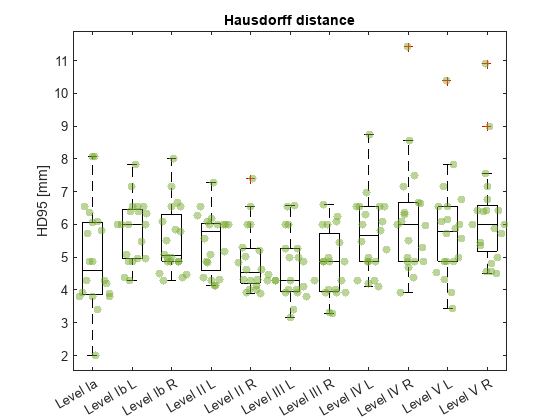


figure(3)
boxplot(similarity.HD95, nameToFind, ...
    Colors='k', BoxStyle='outline')
hold on
ylabel('HD95 [mm]')
title('Hausdorff distance')
swarmchart(x, similarity.HD95, [], ...
    [0.4660 0.6740 0.1880],'filled','MarkerFaceAlpha',0.5, ...
    'MarkerEdgeAlpha',0.5)
hold off
saveas(gcf, '\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\HD95.png')

We need to find out why patient 14 has so high MSD... We start by importing the contours:

dir_list = [{'DAH01'}, {'DAH02'}, {'DAH03'}, {'DAH04'}, {'DAH05'},{'DAH06'}, ...
    {'DAH07'}, {'DAH08'}, {'DAH09'}, {'DAH10'}, {'DAH11'}, {'DAH12'}, {'DAH13'}, ...
    {'DAH14'}, {'DAH15'}, {'DAH16'}, {'DAH17'}, {'DAH18'}, {'DAH19'}, {'DAH20'}];

nameToFind = [ {'Level Ia' }, {'Level Ib L' }, {'Level Ib R' }, ...
        {'Level II L' }, {'Level II R' }, {'Level III L'}, ...
        {'Level III R'}, {'Level IV L' }, {'Level IV R' }, ...
        {'Level V L'  }, {'Level V R'  }];

i = 14;
dir_name = append('\\prapprflstg01\Research\LBV\Level_data_MIM\', dir_list(i))

dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH14'}


[CTimage, spatial, dim, rtContours, info] = read_dicom(dir_name);
[ROI_masks] = ROI_to_mask(rtContours, CTimage, spatial);
    


And plotting them individually:

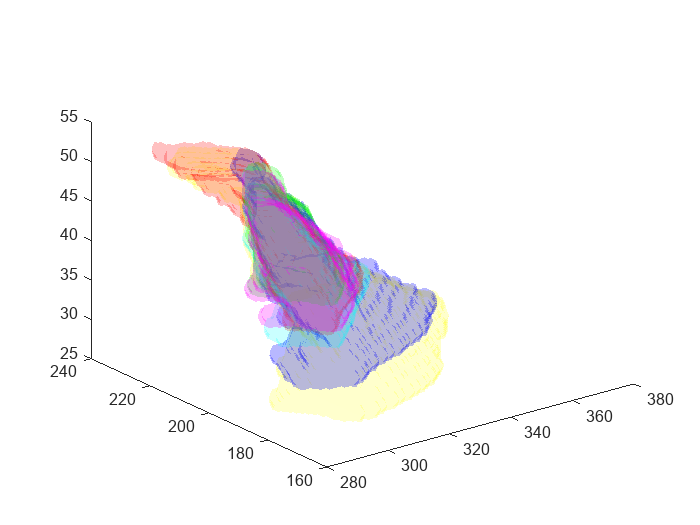

Index in position 2 exceeds array bounds. Index must not exceed 6.

v_x = spatial.PixelSpacings(1);
v_y = spatial.PixelSpacings(2);
v_z = spatial.PatientPositions(2, 3) - spatial.PatientPositions(1, 3);

A = [v_x 0 0 0; 0 v_y 0 0; 0 0 v_z 0; 0 0 0 1];
tform = affinetform3d(A);

figure()

view(3);


col_list = [{'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}];


alpha_list = [0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1];


for i=1:7

    temp2 = ROI_masks{1, i}.Mask{10};
    surf2=isosurface(temp2,0);
    p2 = patch(surf2);
          %isonormals(p1);
    set(p2,'FaceColor',col_list{i},'EdgeColor','none','FaceAlpha',alpha_list(i)); 

end

Seems like one of the contours is very different from the others...

Now we find out what to put in the tables:

for i=1:length(nameToFind)
    similarity.struct{1, i}
    median(similarity.HD95(:, i))
    iqr(similarity.HD95(:, i))
end

ans = 'Level Ia'

ans = 5.4559

ans = 3.5977

ans = 'Level Ib L'

ans = 6.2181

ans = 2.1981

ans = 'Level Ib R'

ans = 5.9780

ans = 3.8175

ans = 'Level II L'

ans = 5.9610

ans = 1.8767

ans = 'Level II R'

ans = 5.3216

ans = 2.0546

ans = 'Level III L'

ans = 5.2557

ans = 2

ans = 'Level III R'

ans = 5.1695

ans = 1.7244

ans = 'Level IV L'

ans = 6.0577

ans = 2.6407

ans = 'Level IV R'

ans = 6.0962

ans = 3.0713

ans = 'Level V L'

ans = 6.3095

ans = 3.0312

ans = 'Level V R'

ans = 6.8498

ans = 3.5321

Super! Now all that is left is pretty 3D plots... Let's see what we can get.

dir_list = [{'DAH01'}, {'DAH02'}, {'DAH03'}, {'DAH04'}, {'DAH05'}, ...
    {'DAH07'}, {'DAH08'}, {'DAH09'}, {'DAH10'}, {'DAH11'}, {'DAH12'}, {'DAH13'}, ...
    {'DAH14'}, {'DAH15'}, {'DAH16'}, {'DAH17'}, {'DAH18'}, {'DAH19'}, {'DAH20'}];

MDS_per_patient = [];
S_per_patient =[];

for i = 1:length(dir_list)

    dir_name = append('\\prapprflstg01\Research\LBV\Level_data_MIM\', dir_list(i))
    [CTimage, spatial, dim, rtContours, info] = read_dicom(dir_name);
    [ROI_masks] = ROI_to_mask(rtContours, CTimage, spatial);
    
    c = 1;
    MDS_mean = [];
    S_mean = [];
    for j = 1:1%length(nameToFind) % number of ROIs
        
        [x, y, z] = find_edges(ROI_masks{1}.Mask{j});
        ROI1 = ROI_masks{1}.Mask{j};
        ROI1 = ROI1(x(1):x(end), y(1):y(end), z(1):z(end));


        for k=2:length(rtContours) % number of doctors drawing

            ROI2 = ROI_masks{k}.Mask{j};
            ROI2 = ROI2(x(1):x(end), y(1):y(end), z(1):z(end));

            [dta, dtb, S, S_prime] = Surface_distances_3D(ROI1, ROI2, spatial);

            MDS = dtb;

            if isempty(MDS_mean)
                MDS_mean = MDS;
            else
                MDS_mean = MDS_mean + MDS;
            end
            
            c = c + 1;
        end
    end

    MDS_per_patient{i} =  MDS_mean ./ c;
    S_per_patient{i} = S;
end

dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH01'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH02'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH03'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH04'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH05'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH07'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH07'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH08'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH09'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH10'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH11'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH12'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH13'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH14'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH15'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH16'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH17'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH18'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH19'}


dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH20'}


Visualizing the structure

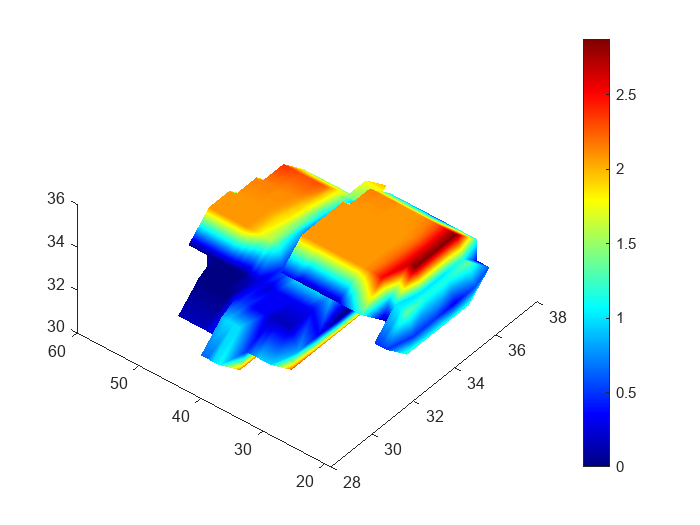

SURF = isosurface(uint8(S_per_patient{11}), 0);
DATA_SURF = interp3(MDS_per_patient{11},SURF.vertices(:,1),SURF.vertices(:,2),SURF.vertices(:,3));
clf
view(3); colormap jet;
colorbar;

patch('Faces',SURF.faces,'Vertices',SURF.vertices,'EdgeColor','none', ...
    'FaceColor','interp','FaceVertexCData',DATA_SURF);

That's all great! But it would be more helpfull if we FIRST found which contour is the most representative of the set:

WE START THE ANALYSIS HERE!!!

dir_list = [{'DAH01'}, {'DAH02'}, {'DAH03'}, {'DAH04'}, {'DAH05'}, ...
    {'DAH07'}, {'DAH08'}, {'DAH09'}, {'DAH10'}, {'DAH11'}, {'DAH12'}, {'DAH13'}, ...
    {'DAH14'}, {'DAH15'}, {'DAH16'}, {'DAH17'}, {'DAH18'}, {'DAH19'}, {'DAH20'}];

MDS_per_patient = [];
S_per_patient =[];
dice_median = [];


for i = 1:1%length(dir_list)

    dir_name = append('\\prapprflstg01\Research\LBV\Level_data_MIM\', dir_list(i))
    [CTimage, spatial, dim, rtContours, info] = read_dicom(dir_name);
    [ROI_masks] = ROI_to_mask(rtContours, CTimage, spatial);
    
    c = 1;
    %MDS_mean = [];
    %S_mean = [];

    
    m = 1;    

    j = 3; % LEVEL WE ARE CALCULATING
  
    % First we check which contour has the lowest DICE (cheaper calculation) to all others
    for k=1:length(rtContours)
        for l=k+1:length(rtContours)
                
            [x, y, z] = find_edges(ROI_masks{1}.Mask{j});
            ROI1 = ROI_masks{k}.Mask{j};
            ROI1 = ROI1(x(1):x(end), y(1):y(end), z(1):z(end));
    
            ROI2 = ROI_masks{l}.Mask{j};
            ROI2 = ROI2(x(1):x(end), y(1):y(end), z(1):z(end));

            dice_median(m, 1) = dice(ROI1, ROI2);
            dice_median(m, 2) = k;
            dice_median(m, 3) = l;
            m = m + 1;
        end 
    end

end

dir_name = 1×1 cell array
    {'\\prapprflstg01\Research\LBV\Level_data_MIM\DAH01'}



% find the contour with lowest DICE to all others:

sorted =  sortrows(dice_median, 1);
best = mode(reshape(sorted(1:5, 2:3), 1, []));


dir_list = [{'DAH01'}, {'DAH02'}, {'DAH03'}, {'DAH04'}, {'DAH05'}, ...
    {'DAH07'}, {'DAH08'}, {'DAH09'}, {'DAH10'}, {'DAH11'}, {'DAH12'}, {'DAH13'}, ...
    {'DAH14'}, {'DAH15'}, {'DAH16'}, {'DAH17'}, {'DAH18'}, {'DAH19'}, {'DAH20'}];

MDS_per_patient = [];
S_per_patient =[];

for i = 1:length(dir_list)

    dir_name = append('\\prapprflstg01\Research\LBV\Level_data_MIM\', dir_list(i))
    [CTimage, spatial, dim, rtContours, info] = read_dicom(dir_name);
    [ROI_masks] = ROI_to_mask(rtContours, CTimage, spatial);
    
    c = 1;
    MDS_mean = [];
    S_mean = [];

    for j = 3:3%length(nameToFind) % number of ROIs
        
        [x, y, z] = find_edges(ROI_masks{best}.Mask{j});
        ROI1 = ROI_masks{best}.Mask{j};
        ROI1 = ROI1(x(1):x(end), y(1):y(end), z(1):z(end));

        for k=1:length(rtContours) % number of doctors drawing
            if k == best
                continue
            end

            ROI2 = ROI_masks{k}.Mask{j};
            ROI2 = ROI2(x(1):x(end), y(1):y(end), z(1):z(end));

            [dta, dtb, S, S_prime] = Surface_distances_3D(ROI1, ROI2, spatial);

            MDS = dtb;

            if isempty(MDS_mean)
                MDS_mean = MDS;
            else
                MDS_mean = MDS_mean + MDS;
            end
            
            c = c + 1;
        end
    end

    MDS_per_patient{i} =  MDS_mean ./ c;
    S_per_patient{i} = S;

end

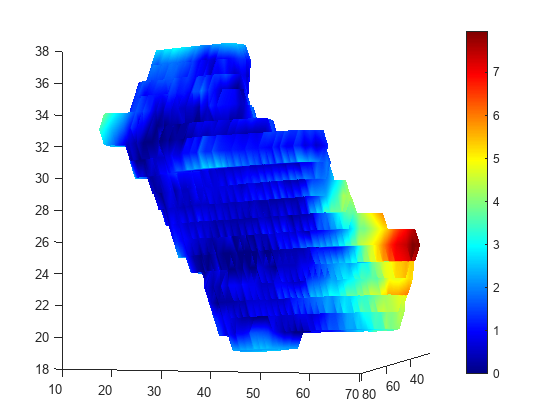

SURF = isosurface(uint8(S_per_patient{3}), 0);
DATA_SURF = interp3(MDS_per_patient{3},SURF.vertices(:,1),SURF.vertices(:,2),SURF.vertices(:,3));
clf
view(3); colormap jet;
colorbar;

patch('Faces',SURF.faces,'Vertices',SURF.vertices,'EdgeColor','none', ...
    'FaceColor','interp','FaceVertexCData',DATA_SURF);

Now we do an image registration between the contours

R_MDS_per_patient = [];
R_MEAN = MDS_per_patient{1};


[optimizer,metric] = imregconfig("multimodal")

optimizer =   registration.optimizer.OnePlusOneEvolutionary

  Properties:
         GrowthFactor: 1.050000e+00
              Epsilon: 1.500000e-06
        InitialRadius: 6.250000e-03
    MaximumIterations: 100

metric =   registration.metric.MattesMutualInformation

  Properties:
    NumberOfSpatialSamples: 500
     NumberOfHistogramBins: 50
              UseAllPixels: 1

optimizer.InitialRadius = 0.001;
optimizer.Epsilon = 1.5e-4;
optimizer.GrowthFactor = 1.01;
optimizer.MaximumIterations = 400;

for i = 2:length(dir_list)

    fixed = int8(S_per_patient{1});
    moving = int8(S_per_patient{i});
   
    tform = imregtform(moving, fixed, "affine", optimizer, metric);

    R_MDS_per_patient{i} = imwarp(MDS_per_patient{i}, tform, "OutputView", imref3d(size(fixed)));
    R_contour_per_patient{i} = imwarp(S_per_patient{i}, tform, "OutputView", imref3d(size(fixed)));

end


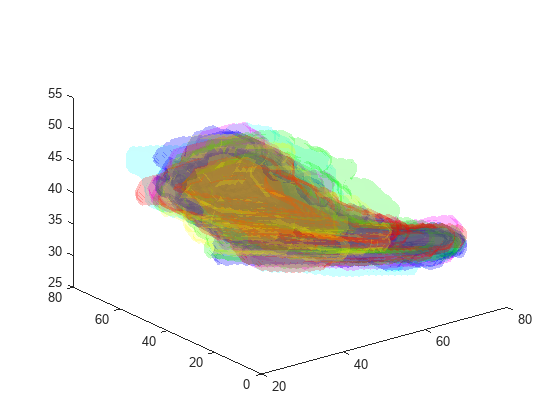

R_contour_per_patient{1} = S_per_patient{1};
R_MDS_per_patient{1} = MDS_per_patient{1};


v_x = spatial.PixelSpacings(1);
v_y = spatial.PixelSpacings(2);
v_z = spatial.PatientPositions(2, 3) - spatial.PatientPositions(1, 3);

A = [v_x 0 0 0; 0 v_y 0 0; 0 0 v_z 0; 0 0 0 1];
tform = affinetform3d(A);

figure()

view(3);


col_list = [{'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}, ...
    {'blue'}, {'magenta'}, {'red'}, {'green'}, {'cyan'}, {'yellow'}];


alpha_list = [0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1, ...
    0.15, 0.14, 0.13, 0.12, 0.11, 0.1];


for i=1:7

    temp2 = R_contour_per_patient{i};
    surf2=isosurface(temp2,0);
    p2 = patch(surf2);
          %isonormals(p1);
    set(p2,'FaceColor',col_list{i},'EdgeColor','none','FaceAlpha',alpha_list(i)); 

end

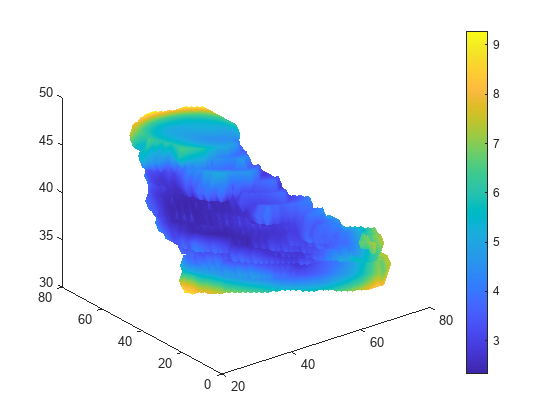

MDS_median = R_MDS_per_patient{1};

for i=2:length(dir_list)
    temp = R_MDS_per_patient{i};
    temp(isnan(temp)) = 0;
    temp(isinf(temp)) = 0;
    MDS_median = MDS_median + temp;
end

MDS_median = MDS_median ./19;

SURF = isosurface(uint8(R_contour_per_patient{1}), 0);
DATA_SURF = interp3(MDS_median,SURF.vertices(:,1),SURF.vertices(:,2),SURF.vertices(:,3));
clf
view(3); colormap parula;
colorbar;

patch('Faces',SURF.faces,'Vertices',SURF.vertices,'EdgeColor','none', ...
    'FaceColor','interp','FaceVertexCData',DATA_SURF);

save(append('\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\images\3d\', 'Test.mat'),'SURF', 'MDS_median');




## **We are nearly done! Only need a few more pretty plots for the paper:**

dir_list = [{'DAH01'}, {'DAH02'}, {'DAH03'}, {'DAH04'}, {'DAH05'},{'DAH06'}, ...
    {'DAH07'}, {'DAH08'}, {'DAH09'}, {'DAH10'}, {'DAH11'}, {'DAH12'}, {'DAH13'}, ...
    {'DAH14'}, {'DAH15'}, {'DAH16'}, {'DAH17'}, {'DAH18'}, {'DAH19'}, {'DAH20'}];

nameToFind = [ {'Level Ia' }, {'Level Ib L' }, {'Level Ib R' }, ...
        {'Level II L' }, {'Level II R' }, {'Level III L'}, ...
        {'Level III R'}, {'Level IV L' }, {'Level IV R' }, ...
        {'Level V L'  }, {'Level V R'  }];

i = 1;
dir_name = append('\\prapprflstg01\Research\LBV\Level_data_MIM\', dir_list(i));
[CTimage, spatial, dim, rtContours, info] = read_dicom(dir_name);

%[ROI_masks] = ROI_to_mask(rtContours, CTimage, spatial);


    set(0,'DefaultFigureVisible','off');
    
    nameToFind = [ {'Level Ia' }, {'Level Ib L' }, {'Level Ib R' }, ...
        {'Level II L' }, {'Level II R' }, {'Level III L'}, ...
        {'Level III R'}, {'Level IV L' }, {'Level IV R' }, ...
        {'Level V L'  }, {'Level V R'  }, {'Boddy_MIM'}];
    
    for i=1:length(rtContours)
        for j=1:length(nameToFind)
            
            contourIndex = int32(find(strcmp(rtContours{i}.ROIs.Name, ...
                nameToFind(j))));
      
            rtMask = createMask(rtContours{i},contourIndex, spatial);
           
            ROI_masks{i}.Name{j} = nameToFind(j);
            ROI_masks{i}.Mask{j} = rtMask;

        end
    end
    set(0,'DefaultFigureVisible','on');




v_x = spatial.PixelSpacings(1);
v_y = spatial.PixelSpacings(2);
v_z = spatial.PatientPositions(2, 3) - spatial.PatientPositions(1, 3);

A = [v_x 0 0 0; 0 v_y 0 0; 0 0 v_z 0; 0 0 0 1];
tform = affinetform3d(A);

Unrecognized function or variable 'affinetform3d'.


fig = figure()

view(3);


col_list = [{'blue'},  {'magenta'},  {'green'}, ...
    {'yellow'},  {'cyan'}, {'red'}, {'black'}];


alpha_list = [0.7, ...
    0.7, 0.7, 0.7, 0.7, 0.7, 0.07];

view(20, 20)

%view(-61.3, 12.4)
axis off

vec = [1, 2, 4, 6, 8, 10, 12]

zlim([45 157])
ylim([100 380])


nameToFind_short = [ {'Level Ia' }, {'Level Ib L' }, ...
        {'Level II L' },  {'Level III L'}, ...
         {'Level IV L' },  ...
        {'Level V L'  }, '{}'];

for i=1:length(vec)

    temp2 = ROI_masks{1}.Mask{vec(i)};
    surf2=isosurface(temp2,0);
    p2 = patch(surf2);
          %isonormals(p1);
    set(p2,'FaceColor',col_list{i},'EdgeColor','none','FaceAlpha',alpha_list(i)); 
    legend(nameToFind_short(i))
end

saveas(fig, append('\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\images\3d\', 'contours.svg'));

Now we only need to save the contours to svg's in the same direction

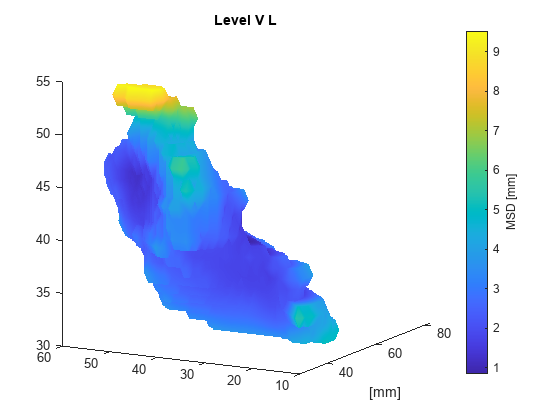

load(append('\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\images\3d\', 'Level V L'),'SURF', 'MDS_median')


DATA_SURF = interp3(MDS_median,SURF.vertices(:,1),SURF.vertices(:,2),SURF.vertices(:,3));
clf
view(3); colormap parula;
colorbar;

title('Level V L')
patch('Faces',SURF.faces,'Vertices',SURF.vertices,'EdgeColor','none', ...
    'FaceColor','interp','FaceVertexCData',DATA_SURF);
cb = colorbar(); 
ylabel(cb,'MSD [mm]')
%view(20, 20)
view(-61.3, 12.4)

xlabel('[mm]')
saveas(fig, append('\\rsyd.net\homedir$\0044\ten9ti\My Documents\Uddannelse\dahanca levels\images\3d\', 'levelVL_side.svg'));